## Estimate model from square wave, validate with sine wave

Hyperparams

clear
trainingFile = "tower_crane_sine_test_data.mat";
validationFile = "tower_crane_square_test_data.mat";
output = "arm";

trainingStruct = load(trainingFile);
validationStruct = load(validationFile);

% sampling time
Ts = 0.002;

Preprocessing: cut off a few seconds

secondsToCutOff =0;
% like this because matlab passes by value
trainingStruct = cutoffBeginning(trainingStruct, Ts, secondsToCutOff);
validationStruct = cutoffBeginning(validationStruct, Ts, secondsToCutOff);
% set options appropriately
tfestOpt = tfestOptions;
ssestOpt = ssestOptions;
initialCondZero = false;
if secondsToCutOff == 0
  initialCondZero = true;
  tfestOpt.InitialCondition = 'zero';
  ssestOpt.InitialState = 'zero';  
end

load training and validation data

[t, y, u] = extractData(trainingStruct, output);
[t_val, y_val, u_val] = extractData(validationStruct, output);

data = iddata(y, u, Ts);
data_val = iddata(y_val, u_val, Ts);

% augment training data
extraTrainingData = false;
if extraTrainingData
    extraDataStruct = load("tower_crane_emile_lennart_data.mat");
    [to, yo, uo] = extractData(extraDataStruct, output);
    extraData = iddata(yo, uo, Ts);
    data = merge(data, extraData);
end

armToPendulum = false;
if armToPendulum
    data = getArmToPendulumData(trainingStruct, Ts);
    data_val = getArmToPendulumData(validationStruct, Ts);
end

constants

N = length(t);
% why this line?
t = (0:Ts:(N-1)*Ts)';

Create data and estimate transfer function

numberPoles = 2

numberPoles = 2



%Gest = tfest(data, 3, 1, 0, opt)
% only specify number of poles
Gest = tfest(data, numberPoles, 0, tfestOpt)

Gest =
 
  From input "u1" to output "y1":
          12.56
  ---------------------
  s^2 + 1.638 s + 5.362
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 75.69%                   
FPE: 0.005701, MSE: 0.005694                     


See fit on training data

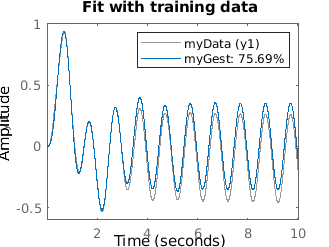

myCompare(data, Gest, initialCondZero, strcat(output, "_train_tfest_np", int2str(numberPoles)))
title('Fit with training data')

See fit on validation data

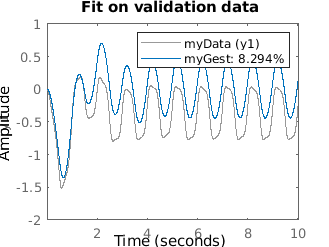

myCompare(data_val, Gest, initialCondZero, strcat(output, "_val_tfest_np", int2str(numberPoles)))
title('Fit on validation data')

Estimate model with ssest

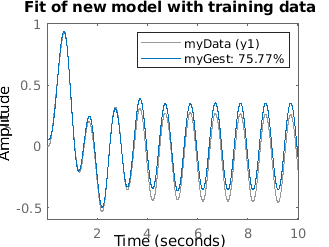

% telling initial state is zero in the options
Gss = ssest(data, 1:10, ssestOpt);
Gest_new = tf(Gss);
% setting initial conditions to false might not be true
myCompare(data, Gest_new, false, strcat(output, "_train_ssest"))
title('Fit of new model with training data')

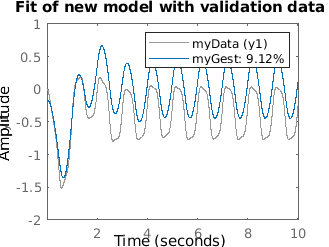

myCompare(data_val, Gest_new, false, strcat(output, "_val_ssest"))
title('Fit of new model with validation data')

if we cut something off for training, compare the obtained model with the entire data

if not(initialCondZero) 
    skipSec = 0
    [t_c, y_c, u_c] = extractCompleteData(trainingStruct, output, Ts, skipSec);
    [t_c_val, y_c_val, u_c_val] = extractCompleteData(validationStruct, output, Ts, skipSec);
    % TODO modular if arm or pendulum
    data_c = iddata(y_c, u_c, Ts);
    data_c_val = iddata(y_c_val, u_c_val, Ts);
    figure
    myCompare(data_c, Gest_new, skipSec == 0, "notRelevant")
    title('Fit of model trained with cutoff data with the complete data')
    
    figure
    myCompare(data_c_val, Gest_new, skipSec == 0, "notRelevant2")
    title('Fit of model trained with cutoff data with the complete data (validation)')
end

Sanity check : system response to constant zero input

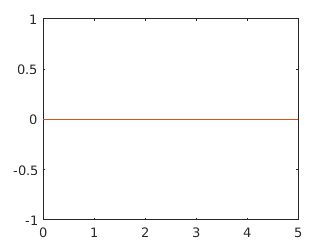

time = 0:Ts:5;
zero_input = zeros(length(time), 1);
zero_response = lsim(Gest, zero_input, time);
zero_response_new = lsim(Gest_new, zero_input, time);

plot(time, [zero_input, zero_response])

plot(time, [zero_input, zero_response_new])

extract complete data in case the normal data is cut off

function result = getArmToPendulumData(dataStruct, Ts)
    data_crane = dataStruct.data_crane;
    y_arm = data_crane(2, :)';
    y_pendulum = data_crane(3, :)';
    result = iddata(y_pendulum, y_arm, Ts);
end

Compare with initial conditions as potentially zero

function myCompare(myData, myGest, initialCondZero, filename)
    path = './dataSoftlink/';
    fitValuePrefix = 'fit_';
    ending = '.txt';
    opt = compareOptions;
    if initialCondZero
        opt.InitialCondition = 'zero';
    end
    compare(myData, myGest, opt);  
    % save to two text files as well
    [ymod, fit, ~] = compare(myData, myGest, opt);
    % time vector
    time = myData.Ts * (0:length(myData.y) - 1)';
    % save one value, skip ... other ones
    skips = 9;
    toSave = [time myData.u myData.y ymod.y];
    toSave = toSave(1:skips + 1:size(toSave, 1), :);
    completeFilename = strcat(path, filename, ending);
    writelines("t u yreal yest", completeFilename);
    writematrix(toSave, completeFilename, 'Delimiter', 'space', 'WriteMode','append');
    writematrix(round(fit, 1), strcat(path, fitValuePrefix, filename, ending), 'Delimiter', 'space');
end

cutoff transitory response

function result = cutoffBeginning(dataStruct, Ts, secondsToCutOff)
    if secondsToCutOff > 0
    dataStruct.data_crane_complete = dataStruct.data_crane;
    dataStruct.data_crane = dataStruct.data_crane(1:end, round(secondsToCutOff / Ts) + 1 : end);
    end
    result = dataStruct;
end